# Péndulo - Nonlinear model

[http://www.sc.ehu.es/sbweb/fisica/dinamica/trabajo/pendulo/pendulo.htm](http://www.sc.ehu.es/sbweb/fisica/dinamica/trabajo/pendulo/pendulo.htm)

Un péndulo simple se define como una partícula (bob) de masa *m* suspendida del punto O por un hilo inextensible de longitud *l* y de masa despreciable.

Si la partícula se desplaza a una posición $\theta_0$ (ángulo que hace el hilo con la vertical) y luego se suelta, el péndulo comienza a oscilar.

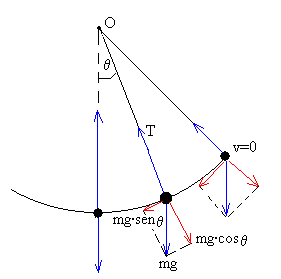

## Ecuación del movimiento en la dirección tangencial (sin fricción)

La aceleración de la partícula es $a_{t\;} =\frac{\mathrm{d}}{\mathrm{d}t}v$ 

La segunda ley de Newton se escribe $m\;a_t =-m\;g\;\textrm{sen}\;\theta$   (fuerza de restauración)

La relación entre la aceleración tangencial y la aceleración angular es $a_t =\alpha \;l$ 

La ecuación del movimiento se escribe en forma de ecuación diferencial


$$\alpha \;l=-g\;\textrm{sen}\;\theta$$



$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\theta =-\frac{g}{l}\;\textrm{sen}\;\theta$$


 
$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\theta +\frac{g}{l}\;\mathrm{sen}\;\theta =0$$


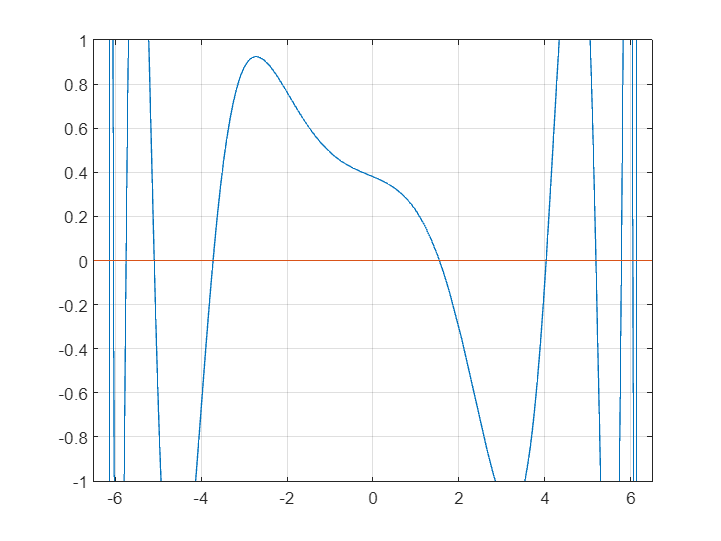

grav = 9.81;
l = 1;
y0 = [pi/8; 0];
T = 2*pi*sqrt(l/grav);
tf = 4*T;

f = @(t,theta) [theta(2);-grav/l*sin(theta(1))];

h = 0.01;
a = 0;
b = tf;
ya = y0(1);
yb = y0(2);

target = 1;
g = @(z0) QuarPar_shooting(f,h,a,b,ya,z0,target)-yb;

fplot(g);grid on; hold on; fplot(@(t)0); hold off;axis([-6.5 6.5 -1 1]);

guess1 = -4.5;
PrimerShoot = g(guess1)

PrimerShoot = -1.6726


za = R4_rfNewton(g,guess1) %Un punto considerablemente cercano

za = 1.5473


y0 = [ya;za];

[t,y] = TerPar_RK4(f, a, y0, h, b);

y(1,end)

ans = -1.2143e-16

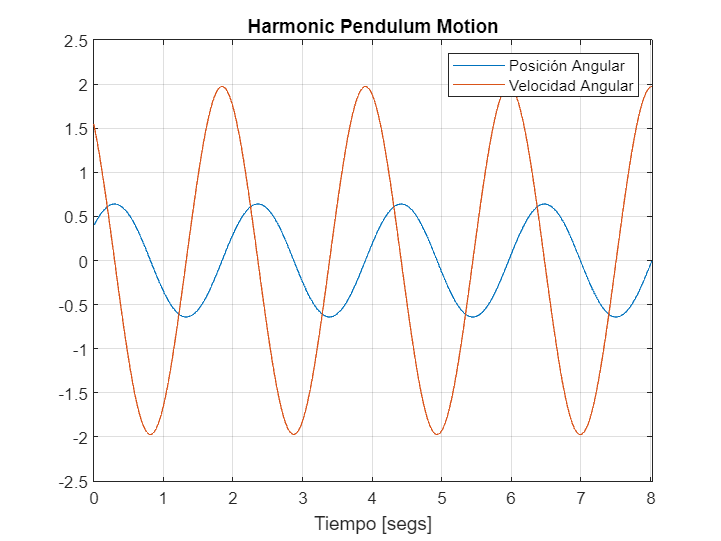

plot(t,y);legend("Posición Angular", "Velocidad Angular");axis([a b -2.5 2.5]);grid on;title('Harmonic Pendulum Motion');hold off;xlabel("Tiempo [segs]");

## Energy analysis

The kinetic energy possessed by an object is the energy it possesses due to its motion. It is a quantity that depends upon both mass and speed. The equation that  relates kinetic energy (KE) to mass (m) and speed (v) is


$$\textrm{KE}=\frac{1}{2}mv^2$$


The faster an object moves, the more kinetic energy that it will possess. 

The potential energy possessed by an object is the stored energy of position. The amount of gravitational potential energy is dependent upon the mass (m) of the object and the height (h) of the object. The equation for gravitational potential energy (PE) is


$$\textrm{PE}=m\;g\;h$$


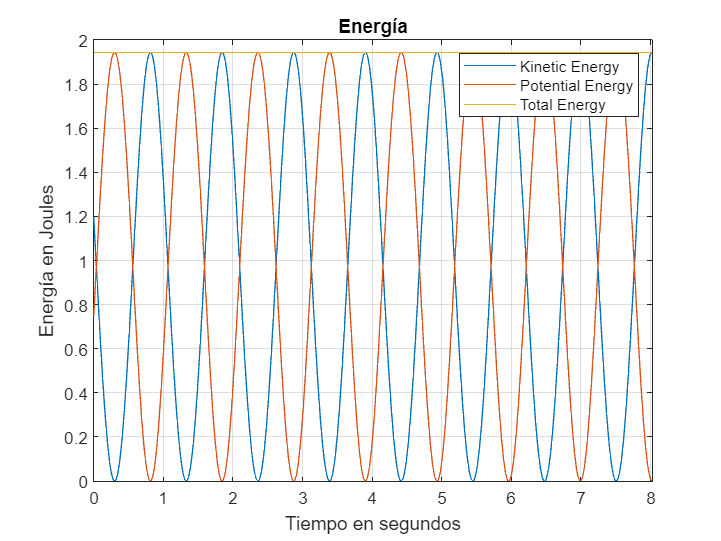

m=1; % como estamos comparando, m no importa
v = y(2,:); %velocidad angular al tiempo t
h = l*(1-cos(y(1,:))); %altura al tiempo y

ke = 0.5*m*v.^2;
pe = m*grav*h; 
plot(t,ke);hold on;plot(t,pe);plot(t,ke+pe);axis([a b 0 2]);
legend("Kinetic Energy", "Potential Energy", "Total Energy");grid on;hold off;title("Energía");
ylabel("Energía en Joules");xlabel("Tiempo en segundos");

## Solución analítica

Creamos la Ecuación Diferencial

syms g l theta(t)
eqn = diff(theta, 2) == - g/l*sin(theta)

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{g\,\sin\left(\theta \left(t\right)\right)}{l}$$

solGeneral = dsolve(eqn)

$$solGeneral = \left(\begin{array}{c} 0\\ 2\,\mathrm{am}\left(\frac{\sqrt{2}\,\sqrt{C_{1}-g}\,\left(C_{2}-t\right)\,\mathrm{i}}{2\,\sqrt{l}}|-\frac{2\,g}{C_{1}-g}\right)\\ -2\,\mathrm{am}\left(\frac{\sqrt{2}\,\sqrt{C_{1}-g}\,\left(C_{2}-t\right)\,\mathrm{i}}{2\,\sqrt{l}}|-\frac{2\,g}{C_{1}-g}\right) \end{array}\right)$$

Dtheta(t) = diff(theta(t),t)

$$Dtheta(t) = \frac{\partial }{\partial t}\theta \left(t\right)$$

conds = [theta(0) == pi/8, Dtheta(0) == 1.5437]

$$conds = \left(\begin{array}{cc} \theta \left(0\right)=\frac{\pi }{8} & \left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)=\frac{15437}{10000} \end{array}\right)$$

solParticular = dsolve(eqn, conds)

 
solParticular =
 
[ empty sym ]
 


Creamos ${\omega_0 }^2 =\frac{g}{l}$, para poder crear aproximaciones reales y garantizar la convergencia de la solución. 

syms omega_0
eqn = subs(eqn, g/l, omega_0^2)

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-{\omega_{0}}^{2}\,\sin\left(\theta \left(t\right)\right)$$

Vamos a aproximar el seno con la serie de Taylor de segundo orden porque no se puede calcular la solución de esta función. Sustituimos nuestra aproximación y conseguimos una equación lineal. 

syms x
approx = taylor(sin(x), x, 'Order', 2)

$$approx = x$$

approx = subs(approx, x, theta(t))

$$approx = \theta \left(t\right)$$

eqnLinear = subs(eqn, sin(theta(t)), approx)

$$eqnLinear(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-{\omega_{0}}^{2}\,\theta \left(t\right)$$

Vamos a crear las condiciones iniciales para la función normal en cero y la función derivada en cero. Es necesario asumir que omega es real. 

syms theta_0 theta_t0
theta_t = diff(theta)

$$theta\_t(t) = \frac{\partial }{\partial t}\theta \left(t\right)$$

cond = [theta(0) == theta_0, theta_t(0) == theta_t0]

$$cond = \left(\begin{array}{cc} \theta \left(0\right)=\theta_{0} & \left({\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)|}_{t=0}\right)=\theta_{\mathrm{t0}} \end{array}\right)$$

assume(omega_0, 'real')

Vamos a solucionar el sistema, primero, notemos que es función de t, segundo notemos que utilizamos la ecuación lineal, tercero la solución es con las condiciones inciales (ojo, sigues sindo simbólicas). 

thetaSol(t) = dsolve(eqnLinear, cond)

$$thetaSol(t) = \theta_{0}\,\cos\left(\omega_{0}\,t\right)+\frac{\theta_{\mathrm{t0}}\,\sin\left(\omega_{0}\,t\right)}{\omega_{0}}$$

Vamos a declarar los valores de las constantes que conocemos, la gravedad, la longitud y el cálculo de omega.

gVal = 9.81;
lVal = 1;
omega_0Val = sqrt(gVal/lVal);
T = 2*pi/omega_0Val;

Ahora vamos a dar nuestras condiciones iniciales. La posición inicial es pi/8 y la velocidad angular inicial es la que calculamos en el ejercicio anterior. 

theta_0Val = pi/8

theta_0Val = 0.3927

theta_t0Val = 1.5473

theta_t0Val = 1.5473

Vamos a crear el vector de variables simbólicas, vamos a crear el vector de los valores que van a sustituir a esos valores. Sustituimos. 

vars   = [omega_0 theta_0 theta_t0];
values = [omega_0Val theta_0Val theta_t0Val];
thetaSolPlot = subs(thetaSol,vars,values);

Graficamos. 

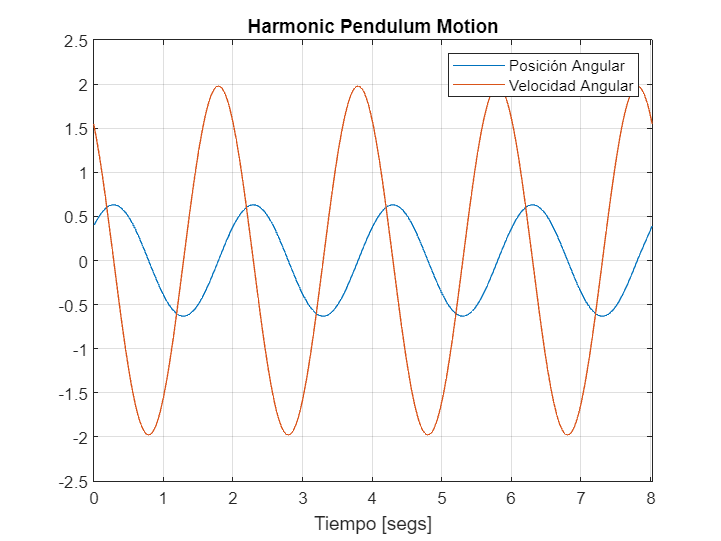

fplot(thetaSolPlot(t), [0 4*T]);hold on;fplot(diff(thetaSolPlot, t), [0 4*T]);grid on;title('Harmonic Pendulum Motion');axis([a b -2.5 2.5]);legend("Posición Angular", "Velocidad Angular");hold off;xlabel("Tiempo [segs]");